# Brain states

Matlab live script for computer practical Neurophysics course

2024, Alexander Heimel

## To do

## Load spike data

Load a dataset from a Neuropixels electrophysiology recording of mouse V1 units while the mouse is observing trials of drifting gratings of 12 different orientations.

params = bs_default_params();
addpath(fullfile(fileparts(which('brainstates.mlx')),'Mutualinfo'));

[spike_times,trial_stim_on,trial_stim_off,trial_stim_type, recording_interval] = bs_load_data(params);

Loaded 127 clusters and 480 trials for 12 different stimuli.
Stimulus typeRunDriftingGratings



params.smooth = true;
params.smooth_function = 'smoothen';
params.smooth_window = 0.1;
params.binsize = 0.01;

[bin_times,bin_counts,bin_labels,bin_times_rel] = ...
    bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,trial_stim_type, recording_interval,params);
n_bins = length(bin_times);

% create a subset to speed up graphs and computations (especially for t-sne)
ind_bin_subset = round(linspace(1,n_bins,min([1000 n_bins]))); 

## Principal components analysis

Principal component analysis (PCA) is a linear dimensionality reduction technique with applications in exploratory data analysis, visualization and data preprocessing. The data is linearly transformed onto a new coordinate system such that the directions (principal components) capturing the largest variation in the data can be easily identified [[https://en.wikipedia.org/wiki/Principal_component_analysis](https://en.wikipedia.org/wiki/Principal_component_analysis)].

## PCA Example with two neurons

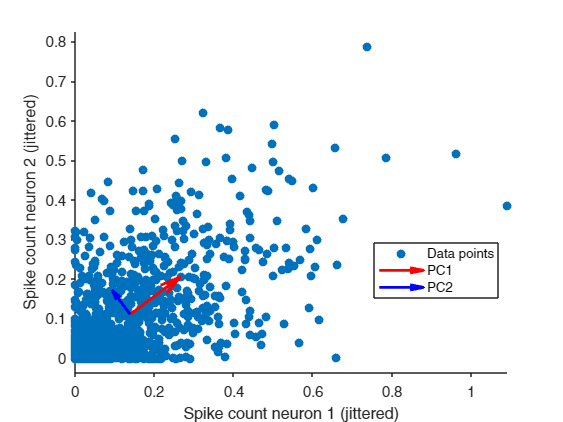

c1 = 15;
c2 = 19;
x = bin_counts([c1 c2],:)';
[coeff,score,latent] = pca(x);

figure
scatter(bin_counts(c1,ind_bin_subset),...
    bin_counts(c2,ind_bin_subset) ,'filled')
xlabel('Spike count neuron 1 (jittered)');
ylabel('Spike count neuron 2 (jittered)');
axis equal

% Plot the first two principal components
hold on
x_mean = mean(x);
quiver(x_mean(1), x_mean(2), ...
       coeff(1, 1) * sqrt(latent(1)), coeff(2, 1) * sqrt(latent(1)), ...
       'r', 'LineWidth', 2, 'MaxHeadSize', 2);
quiver(x_mean(1), x_mean(2), ...
       coeff(1, 2) * sqrt(latent(2)), coeff(2, 2) * sqrt(latent(2)), ...
       'b', 'LineWidth', 2, 'MaxHeadSize', 2);
legend('Data points', 'PC1', 'PC2', 'Location', 'best');

## PCA for all clusters

disp('Computing PCA')

Computing PCA


x = bin_counts';
[coeff,score,~,~,explained] = pca(x);
x_mean = mean(x); 

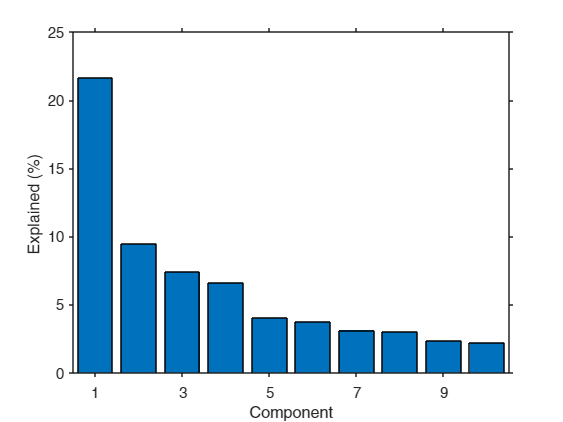

figure
bar(explained)
ylabel('Explained (%) ')
xlabel('Component')
xlim([0.5 10.5])
set(gca,'xtick',1:2:10)

### Excercise

Reconstruct the data from the first 3 principal components. Plot the original data and the reconstructed data.

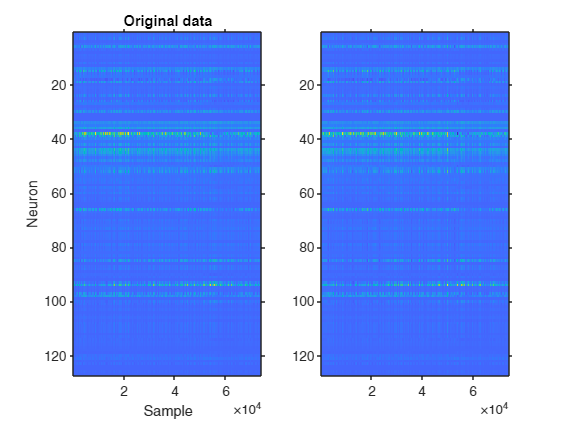

x_reconstruct = score(:,(1:3))*coeff(:,(1:3))' + repmat(x_mean,n_bins,1);
imagesc(x_reconstruct')

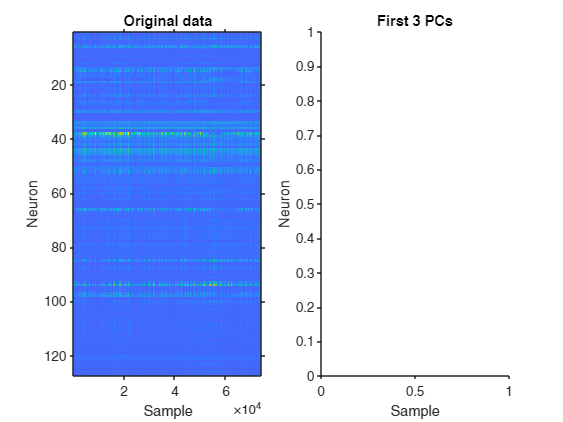


figure
subplot(1,2,1)
imagesc(x')
ylabel('Neuron')
xlabel('Sample')
title('Original data')

subplot(1,2,2)
ylabel('Neuron')
xlabel('Sample')
title('First 3 PCs')

## PC1 vs PC2 with time since stimulus on as color

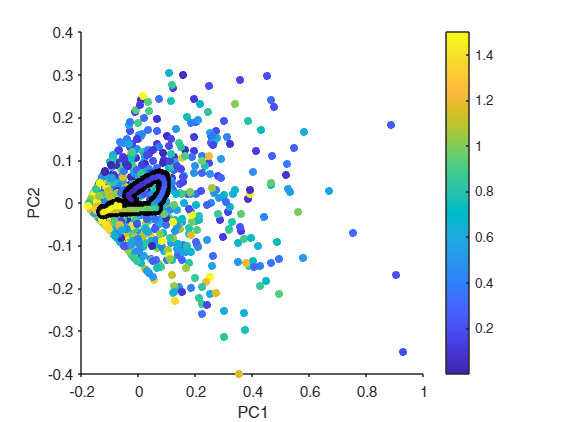

figure;
scatter(score(ind_bin_subset,1),score(ind_bin_subset,2),30,bin_times_rel(ind_bin_subset),'filled')
axis square
colorbar
xlabel('PC1')
ylabel('PC2')

% Plot moving average
hold on
[~,ind] = sort(bin_times_rel);
x = movingavr(score(ind,1),2000);
x_tsne = movingavr(score(ind,2),2000);
plot(x,x_tsne,'k-','linewidth',10)
scatter(x,x_tsne,10,bin_times_rel(ind),'filled')

## PC1 vs PC2 with label as color

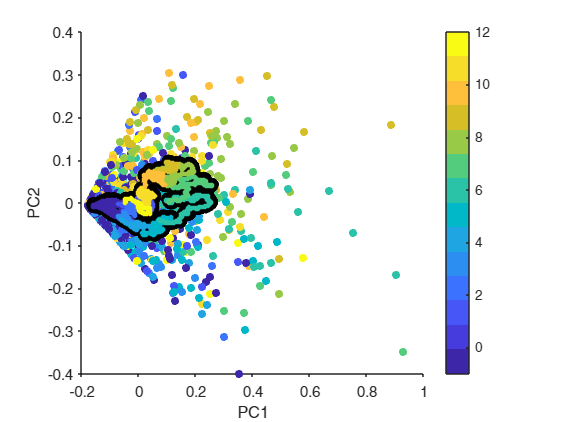

figure;
scatter(score(ind_bin_subset,1),score(ind_bin_subset,2),30,bin_labels(ind_bin_subset),'filled')
colormap(parula(max(bin_labels(ind_bin_subset))+2))

axis square
colorbar
xlabel('PC1')
ylabel('PC2')

% Plot moving average
hold on
[~,ind] = sort(bin_labels);
x = movingavr(score(ind,1),2000);
x_tsne = movingavr(score(ind,2),2000);
plot(x,x_tsne,'k-','linewidth',10)
scatter(x,x_tsne,10,bin_labels(ind),'filled')

## Factor analysis

Factor analysis is a statistical method used to describe variability among observed, correlated variables in terms of a potentially lower number of unobserved variables called factors. For example, it is possible that variations in six observed variables mainly reflect the variations in two unobserved (underlying) variables. Factor analysis searches for such joint variations in response to unobserved latent variables. The observed variables are modelled as linear combinations of the potential factors plus "error" terms, hence factor analysis can be thought of as a special case of errors-in-variables models [[https://en.wikipedia.org/wiki/Factor_analysis]](https://en.wikipedia.org/wiki/Factor_analysis).

[~,~,~,~,score] = factoran(bin_counts',10);

## First two factors with time since stimulus on as color

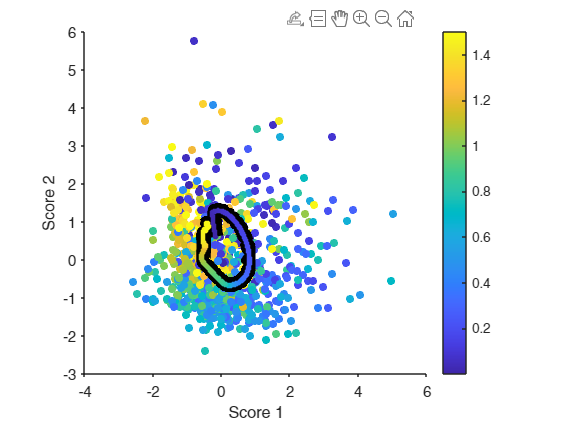


figure;
scatter(score(ind_bin_subset,1),score(ind_bin_subset,2),30,bin_times_rel(ind_bin_subset),'filled')
axis square
colorbar
xlabel('Score 1')
ylabel('Score 2')
hold on

% Plot moving average
[~,ind] = sort(bin_times_rel);
x = movingavr(score(ind,1),2000);
x_tsne = movingavr(score(ind,2),2000);
plot(x,x_tsne,'k-','linewidth',10)
scatter(x,x_tsne,10,bin_times_rel(ind),'filled')

### Exercise

Plot first two factors with label as color

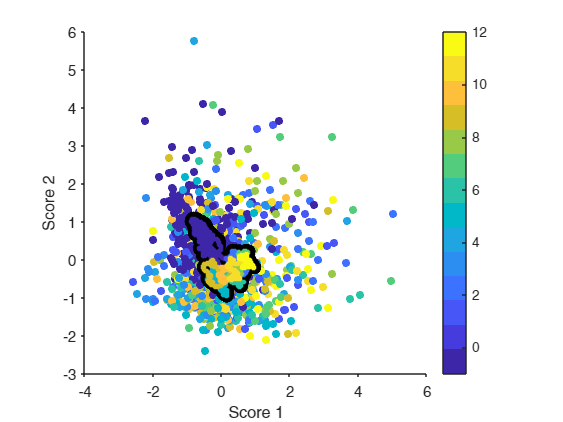

%% Solution
figure
scatter(score(ind_bin_subset,1),score(ind_bin_subset,2),30,bin_labels(ind_bin_subset),'filled')
colormap(parula(max(bin_labels(ind_bin_subset))+2))
axis square
colorbar
xlabel('Score 1')
ylabel('Score 2')
hold on

% Plot moving average
[~,ind] = sort(bin_labels);
x = movingavr(score(ind,1),2000);
x_tsne = movingavr(score(ind,2),2000);
plot(x,x_tsne,'k-','linewidth',10)
scatter(x,x_tsne,10,bin_labels(ind),'filled')

## Visualizing high-dimensional data - t-SNE

t-distributed stochastic neighbor embedding (t-SNE) is a nonlinear dimensionality reduction technique for embedding high-dimensional data for visualization in a low-dimensional space of two or three dimensions. Specifically, it models each high-dimensional object by a two- or three-dimensional point in such a way that similar objects are modeled by nearby points and dissimilar objects are modeled by distant points with high probability [[https://en.wikipedia.org/wiki/T-distributed_stochastic_neighbor_embedding](https://en.wikipedia.org/wiki/T-distributed_stochastic_neighbor_embedding)]. A popular alternative is UMAP.

disp('Computing t-sne')

Computing t-sne


rng(1)
x_tsne = tsne(bin_counts(:,ind_bin_subset)');

### Show t-sne with time as color

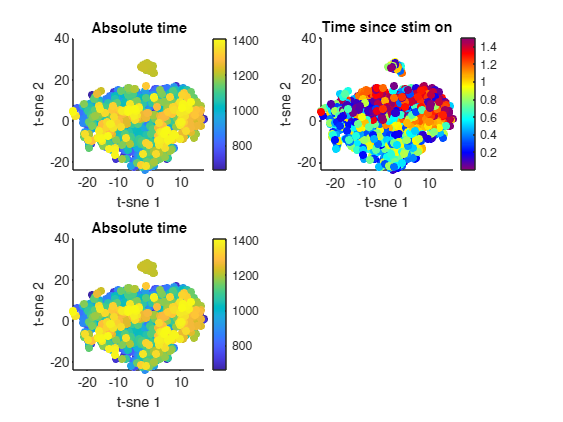

figure
colormap(h,'parula')

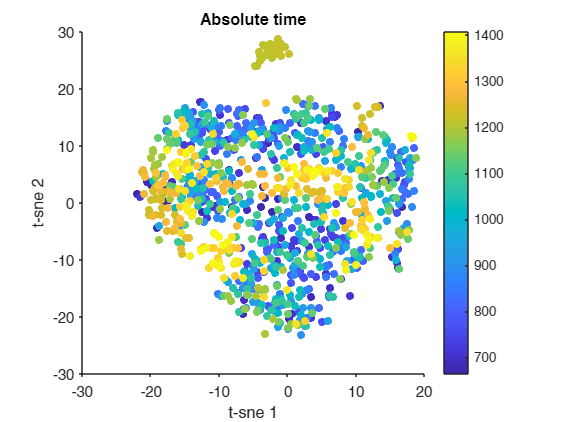

scatter(x_tsne(:,1),x_tsne(:,2),30,bin_times(ind_bin_subset),'filled')
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colorbar
title('Absolute time')

### Show t-sne with time since stim onset as color

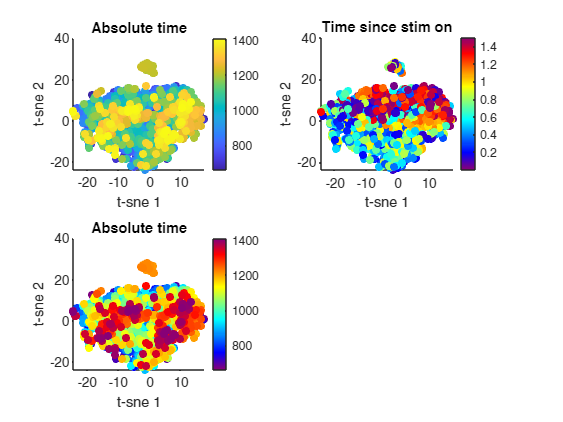

figure
c = bin_times_rel(ind_bin_subset);
scatter(x_tsne(:,1),x_tsne(:,2),30,c,'filled')
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colormap(h,periodic_colormap(128))

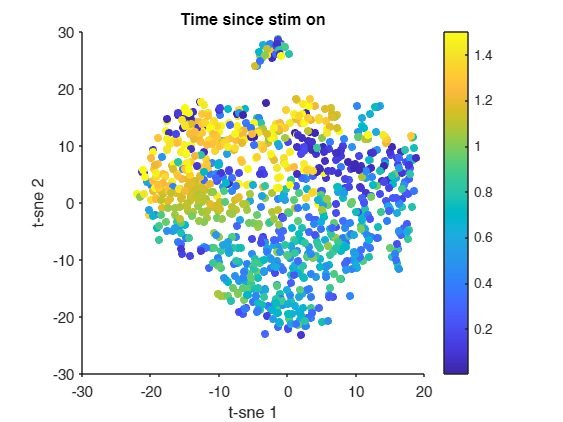

colorbar
title('Time since stim on')

### Show t-sne with stim type as color

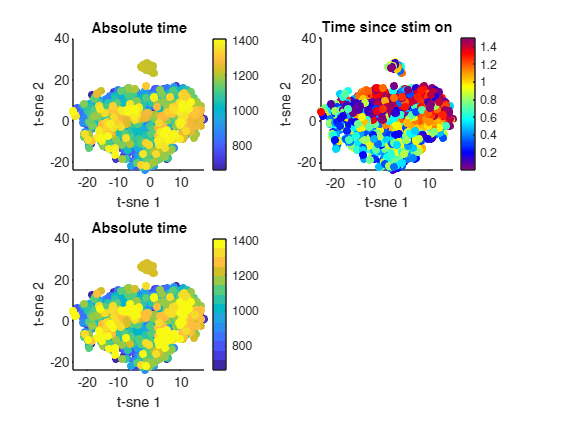

figure
c = bin_labels(ind_bin_subset)+2;
scatter(x_tsne(:,1),x_tsne(:,2),30,c,'filled')
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colormap(h,parula(max(bin_labels(ind_bin_subset))+2))

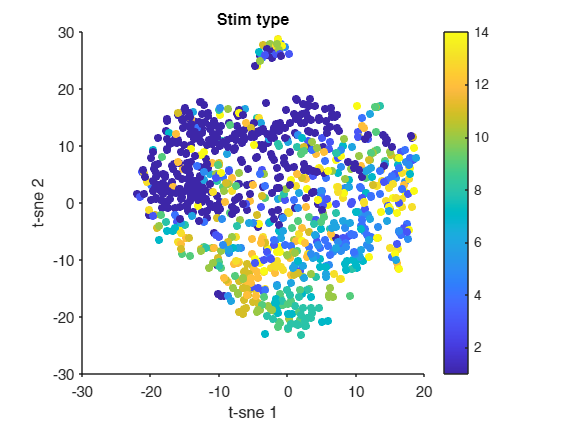

colorbar
title('Stim type')

## Clustering - k-means

k-means clustering is a method of vector quantization, originally from signal processing, that aims to partition n observations into k clusters in which each observation belongs to the cluster with the nearest mean (cluster centers or cluster centroid), serving as a prototype of the cluster. This results in a partitioning of the data space into Voronoi cells. k-means clustering minimizes within-cluster variances (squared Euclidean distances) [[https://en.wikipedia.org/wiki/K-means_clustering](https://en.wikipedia.org/wiki/K-means_clustering)]. 

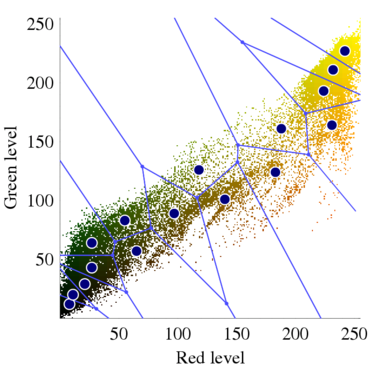

% kmeans of original data
n_clusters = 10;
idx = kmeans(bin_counts',n_clusters);

### Show t-sne with cluster as color

figure
scatter(x_tsne(:,1),x_tsne(:,2),30,idx(ind_bin_subset),'filled')

Index exceeds the number of array elements. Index must not exceed 1000.

axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colormap(h,parula(n_clusters))
colorbar
title('Stim type')

### Cluster based on t-sne transform

idx = kmeans(x_tsne,n_clusters);

### Show t-sne with cluster as color

figure
scatter(x_tsne(:,1),x_tsne(:,2),30,idx,'filled')

Error using scatter
Color must be one RGB triplet, an m-by-3 matrix of RGB triplets with one color per scatter point, or an m-by-1 vector with one value per scatter point.

axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colormap(h,parula(n_clusters))
colorbar
title('Stim type')


### Exercise

Remove outlying cluster and run t-sne again

% solution
rng(1)
x = bin_counts(:,ind_bin_subset(idx~=1))';

Index in position 2 exceeds array bounds. Index must not exceed 7426.

x_tsne = tsne(x);

figure
c = bin_times_rel(ind_bin_subset(idx~=1))';
scatter(x_tsne(:,1),x_tsne(:,2),30,c,'filled')
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colorbar
title('Time since stim on')

## Gaussian mixture

A gaussian mixture model assumes the data to be generated from a mixture of gaussian probability distributions. The gaussians will have different means and covariances. 

n_clusters = 10;
gmfit = fitgmdist(x_tsne,n_clusters,'CovarianceType','full','RegularizationValue',0.01);
post = posterior(gmfit,x_tsne);
idx = cluster(gmfit,x_tsne);
%[~,idx] = max(post,[],2);

### Show clusters with maximum likelihood

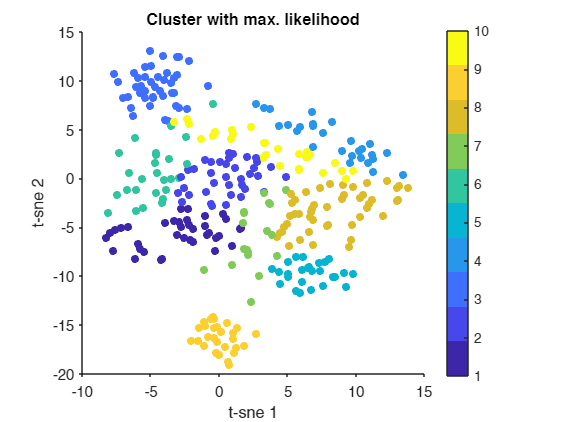

figure
scatter(x_tsne(:,1),x_tsne(:,2),30,idx,'filled')
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colormap(parula(n_clusters))
colorbar
title('Cluster with max. likelihood')

### Exercise

Show likelihood of cluster 1

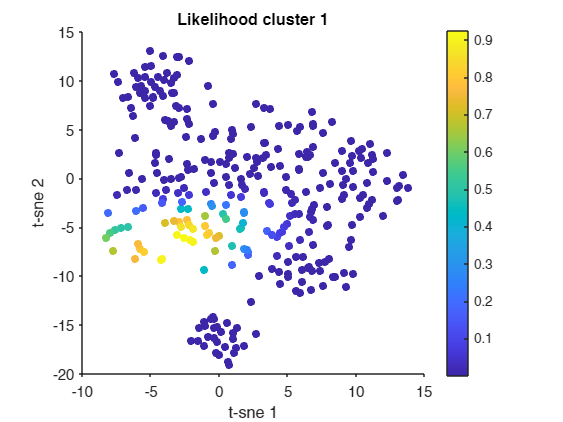

% solution
figure
scatter(x_tsne(:,1),x_tsne(:,2),30,post(:,1),'filled')
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colorbar
title('Likelihood cluster 1')

## Hidden Markov Models

A Hidden Markov Model (HMM) is a set of states and transition probabilities to change from one state to another at each time step. At each time step, an emission (observation) is generated, chosen with a probability distribution that depends on the state [[https://en.wikipedia.org/wiki/Hidden_Markov_model](https://en.wikipedia.org/wiki/Hidden_Markov_model)]. A nice reference for fitting an HMM to neural data is Bagi et al. (Curr Biol 2022).

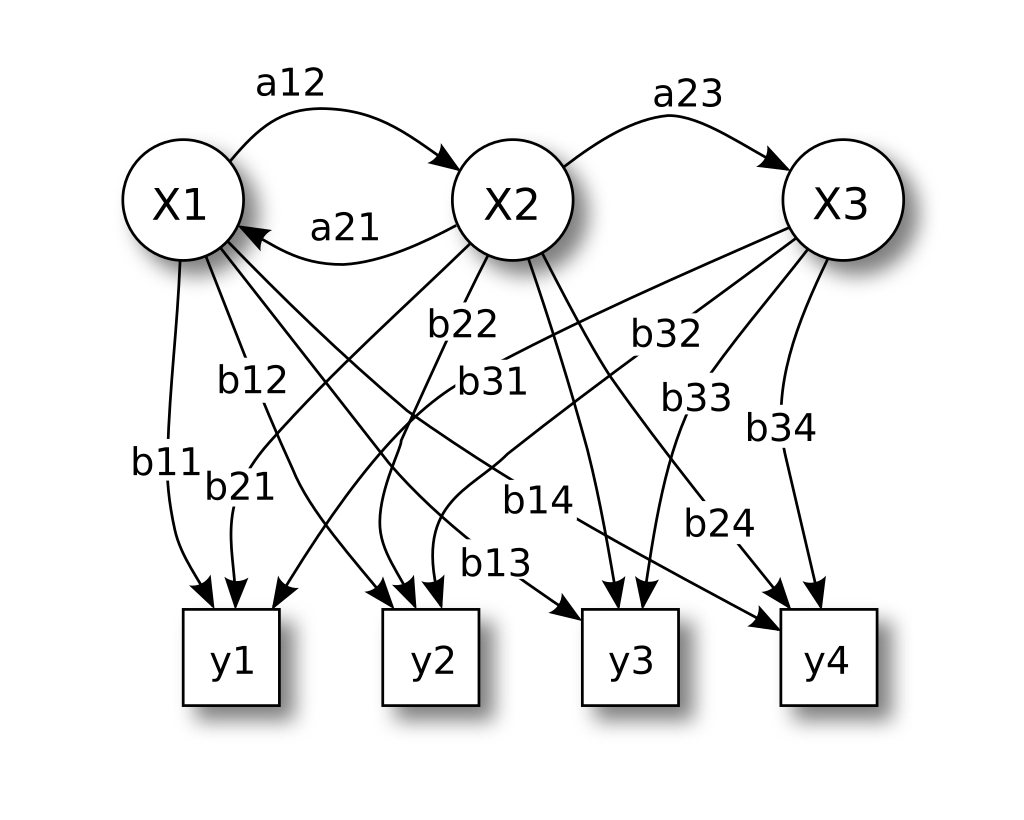

Matlab has in-built functions for training and decoding an HMM (e.g. hmmtrain). 

Gaussian emissions: [https://github.com/probml/pmtk3/tree/master/toolbox/LatentVariableModels/hmm](https://github.com/probml/pmtk3/tree/master/toolbox/LatentVariableModels/hmm)

### Two state HMM on trial structure with hint

Confusion in state = 0. Lower is better.
Confusion in label = 0.46. Lower is better.
Entropy in labels = 3.2
Mutual information in states and labels = 0.94
Relative mutual information = 29%


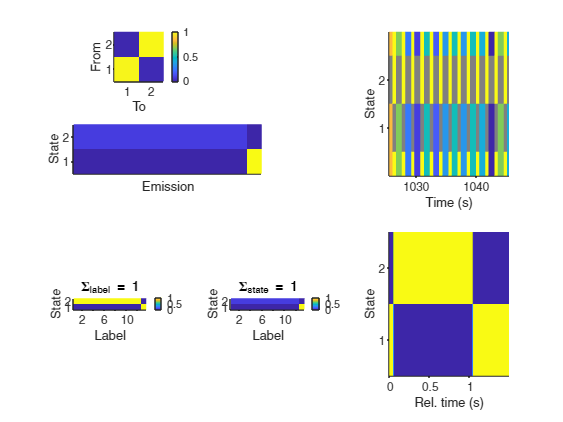

n_states = 2;

params = bs_default_params();
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = ...
    bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,trial_stim_type,recording_interval,params);
bin_labels(bin_labels==-1) = 13;

trans_guess = [ 0.99 0.01; 0.01 0.99];
emis_guess = [0 0 0 0 0 0 0 0 0 0 0 0 1; ...
              1 1 1 1 1 1 1 1 1 1 1 1 0];

bin_data = bin_labels;
[trans,emis] = hmmtrain(bin_data,trans_guess,emis_guess);
p_states = hmmdecode(bin_data,trans,emis);
[~,bin_states] = max(p_states);

bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

### Two state HMM on trial labels without hint

Confusion in state = 0. Lower is better.
Confusion in label = 0.66. Lower is better.
Entropy in labels = 3.2
Mutual information in states and labels = 0.84
Relative mutual information = 26%


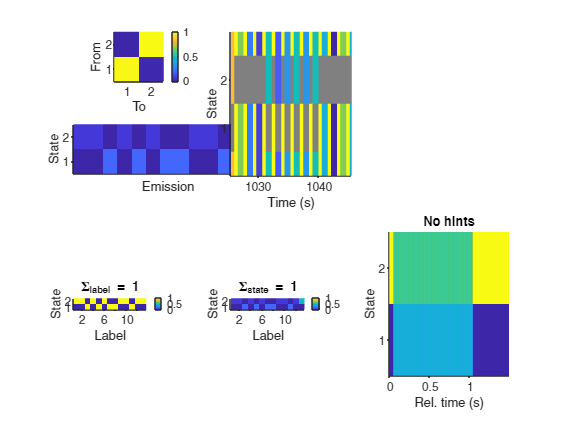

n_states = 2;
params = bs_default_params();
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = ...
    bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,trial_stim_type, recording_interval,params);
bin_labels(bin_labels==-1) = 13;
trans_guess = [0.9 0.1; 0.1 0.9];
emis_guess = rand(n_states,13);
emis_guess = emis_guess ./ sum(emis_guess,2);
bin_data = bin_labels;
[trans,emis] = hmmtrain(bin_data,trans_guess,emis_guess);
p_states = hmmdecode(bin_data,trans,emis);
[~,bin_states] = max(p_states);
bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

### Two state HMM on spike counts (overfitting)

n_states = 2;
params = bs_default_params();
params.fit_hmm_prompt = 'emission_freqs';
params.binsize = 0.1;
params.smooth = false;
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,ones(size(trial_stim_type)), recording_interval,params);
n_emissions = length(bin_times);
[bin_states,~,trans,emis] = bs_fit_hmm(bin_counts,n_states,n_emissions,bin_labels,params);

Fitting HMM
Done fitting


Confusion in state = 0. Lower is better.
Confusion in label = 0. Lower is better.
Entropy in labels = 0.94
Mutual information in states and labels = 0.94
Relative mutual information = 100%


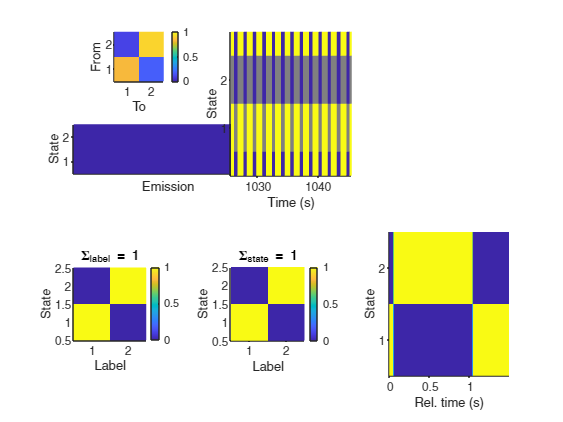

bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

### Two state HMM on spike counts with hint

n_emissions = 10;
n_states = 2;
params = bs_default_params();
params.fit_hmm_prompt = 'emission_freqs';
params.hmm_algorithm = 'Viterbi';
params.smooth = false;
params.binsize = 0.1;
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,ones(size(trial_stim_type)),recording_interval,params);
[bin_states,~,trans,emis] = bs_fit_hmm(bin_counts,n_states,n_emissions,bin_labels,params);

Fitting HMM
Done fitting


Confusion in state = 0.16. Lower is better.
Confusion in label = 0.15. Lower is better.
Entropy in labels = 0.94
Mutual information in states and labels = 0.36
Relative mutual information = 38%


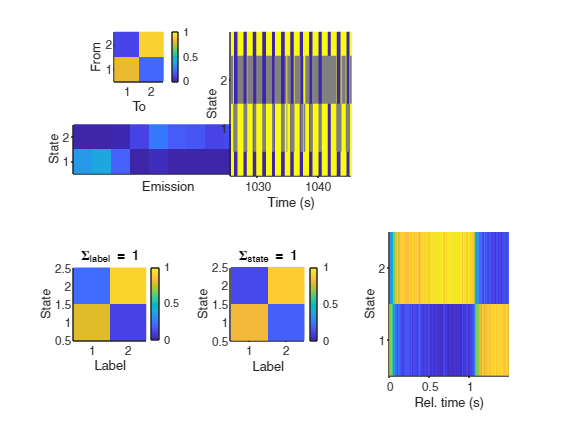

bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

### Two state HMM on first 30 PCs with hint

n_emissions = 100;
n_states = 2;
params = bs_default_params();
params.fit_hmm_prompt = 'emission_freqs';
params.hmm_algorithm = 'Viterbi';
params.smooth = true;
params.square_root_transformation = true;
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,ones(size(trial_stim_type)),recording_interval,params);
[coeff,score,latent] = pca(bin_counts');
score = score(:,1:30);
[bin_states,~,trans,emis] = bs_fit_hmm(score',n_states,n_emissions,bin_labels,params);

Fitting HMM


Done fitting


Confusion in state = 0.14. Lower is better.
Confusion in label = 0.16. Lower is better.
Entropy in labels = 0.94
Mutual information in states and labels = 0.38
Relative mutual information = 40%


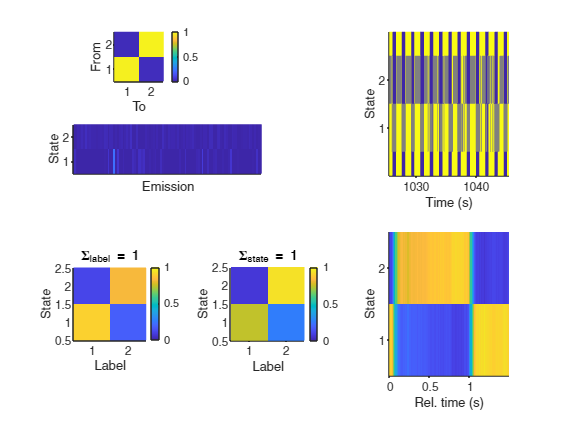

bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

### Two state HMM on first 10 FA components

n_emissions = 100;
n_states = 2;
params = bs_default_params();
params.fit_hmm_prompt = 'emission_freqs';
params.hmm_algorithm = 'Viterbi';
params.smooth = true;
params.smooth_function = 'smoothen';
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,ones(size(trial_stim_type)),recording_interval,params);
[~,~,~,~,bin_scores] = factoran(bin_counts',10);

[bin_states,~,trans,emis] = bs_fit_hmm(bin_scores',n_states,n_emissions,bin_labels,params);

Fitting HMM


Done fitting


Confusion in state = 0.13. Lower is better.
Confusion in label = 0.14. Lower is better.
Entropy in labels = 0.94
Mutual information in states and labels = 0.42
Relative mutual information = 44%


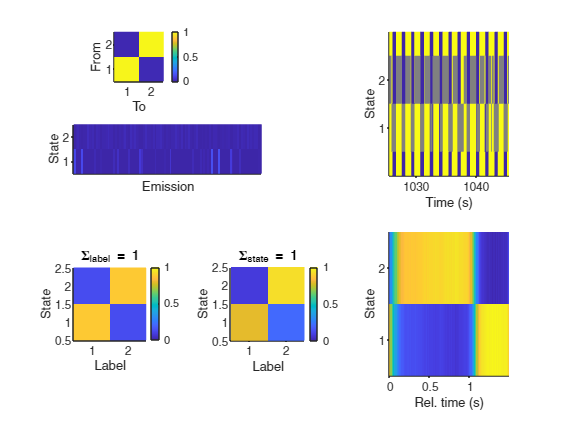

bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

### Two state GM-HMM on first 10 FA components

n_emissions = 10;
n_states = 2;
params = bs_default_params();
params.fit_hmm_prompt = 'mix_gauss_hints';
params.smooth = true;
params.hmm_version = 'Probml_mixgausstied';
params.n_mixgauss = 6; 
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,ones(size(trial_stim_type)),recording_interval,params);
[~,~,~,~,score] = factoran(bin_counts',10);

[bin_states,~,trans,emis] = bs_fit_hmm(score',n_states,n_emissions,bin_labels,params);

Fitting HMM
initializing model for EM
1	 loglik: -251388
2	 loglik: -230910
3	 loglik: -212648
4	 loglik: -186768
5	 loglik: -160143
6	 loglik: -150969
7	 loglik: -145723
8	 loglik: -142743
9	 loglik: -141225
10	 loglik: -140316
11	 loglik: -139288
12	 loglik: -136665
13	 loglik: -134070
14	 loglik: -133208
15	 loglik: -132732
16	 loglik: -132455
17	 loglik: -132253
18	 loglik: -132059
19	 loglik: -131630
20	 loglik: -130990
21	 loglik: -130848
22	 loglik: -130777
23	 loglik: -130714
24	 loglik: -130659
25	 loglik: -130619
26	 loglik: -130589
27	 loglik: -130568
28	 loglik: -130554
29	 loglik: -130544
initializing model for EM
1	 loglik: -734996
2	 loglik: -725516
3	 loglik: -718375
4	 loglik: -712168
5	 loglik: -707128
6	 loglik: -703282
7	 loglik: -700370
8	 loglik: -698057
9	 loglik: -696320
10	 loglik: -694795
11	 loglik: -692452
12	 loglik: -681520
13	 loglik: -664804
14	 loglik: -654489
15	 loglik: -643689
16	 loglik: -634797
17	 loglik: -628471
18	 loglik: -624665
19	 loglik: -6

Confusion in state = 0.12. Lower is better.
Confusion in label = 0.15. Lower is better.
Entropy in labels = 0.94
Mutual information in states and labels = 0.45
Relative mutual information = 48%
STILL TO IMPLEMENT emis.mu


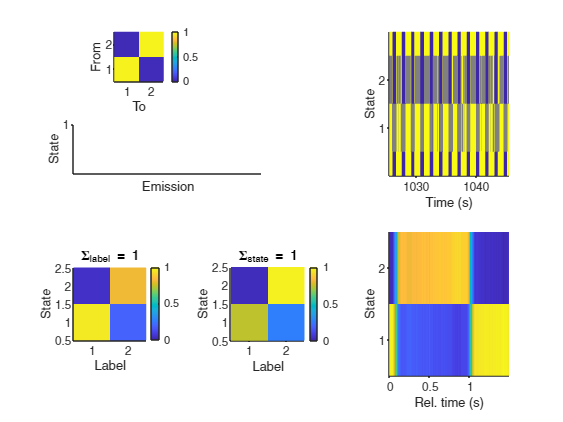

bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

## Two state HMM without hint

n_emissions = 10;
n_states = 2;
params = bs_default_params();
params.fit_hmm_prompt = 'no_hints';
params.hmm_algorithm = 'BaumWelch';
params.smooth = false;
params.binsize = 0.1;
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,ones(size(trial_stim_type)),recording_interval,params);
[bin_states,~,trans,emis] = bs_fit_hmm(bin_counts,n_states,n_emissions,bin_labels,params);

Fitting HMM
Done fitting


Confusion in state = 0.33. Lower is better.
Confusion in label = 0.34. Lower is better.
Entropy in labels = 0.94
Mutual information in states and labels = 0.082
Relative mutual information = 9%


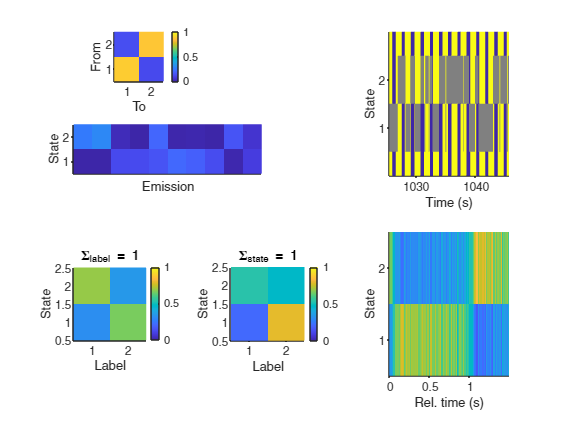

bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

## Two state GM-HMM without hint

n_emissions = 10;
n_states = 2;
params = bs_default_params();
params.fit_hmm_prompt = 'no_mix_gauss_hints';
params.smooth = true;
params.hmm_version = 'Probml_mixgausstied';
params.n_mixgauss = 12; 
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,ones(size(trial_stim_type)),recording_interval,params);
[~,~,~,~,score] = factoran(bin_counts',10);

[bin_states,~,trans,emis] = bs_fit_hmm(score',n_states,n_emissions,bin_labels,params);

Fitting HMM
initializing model for EM
1	 loglik: -1.0046e+06
2	 loglik: -972346
3	 loglik: -947682
4	 loglik: -903890
5	 loglik: -899024
6	 loglik: -894876
7	 loglik: -887330
8	 loglik: -845366
9	 loglik: -791383
10	 loglik: -777910
11	 loglik: -770184
12	 loglik: -765694
13	 loglik: -763050
14	 loglik: -761381
15	 loglik: -760201
16	 loglik: -759263
17	 loglik: -758465
18	 loglik: -757695
19	 loglik: -756618
20	 loglik: -754105
21	 loglik: -747304
22	 loglik: -735040
23	 loglik: -731312
24	 loglik: -729369
25	 loglik: -728068
26	 loglik: -727106
27	 loglik: -726372
28	 loglik: -725793
29	 loglik: -725344
30	 loglik: -724998
31	 loglik: -724711
32	 loglik: -724453
33	 loglik: -724239
34	 loglik: -724061
35	 loglik: -723894
36	 loglik: -723730
37	 loglik: -723563
38	 loglik: -723391
39	 loglik: -723219
40	 loglik: -723051
41	 loglik: -722893
42	 loglik: -722750
43	 loglik: -722622
44	 loglik: -722509
45	 loglik: -722411
46	 loglik: -722329
47	 loglik: -722260
Done fitting


Confusion in state = 0.29. Lower is better.
Confusion in label = 0.31. Lower is better.
Entropy in labels = 0.94
Mutual information in states and labels = 0.061
Relative mutual information = 6%
STILL TO IMPLEMENT emis.mu


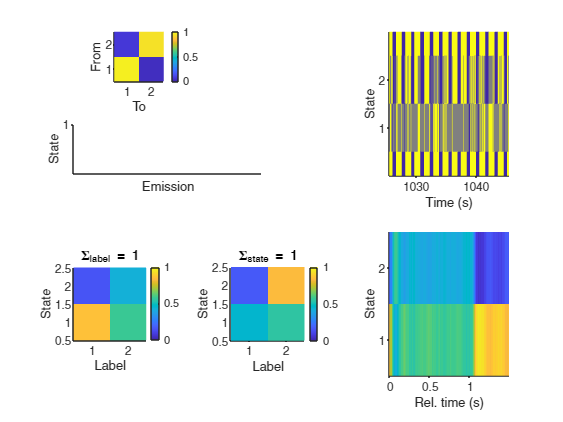

bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

## GM-HMM on first 10 FA components with hint

n_emissions = 10;
params = bs_default_params();
params.fit_hmm_prompt = 'mix_gauss_hints';
params.smooth = true;
params.hmm_version = 'Probml_mixgausstied';
params.n_mixgauss = 6; 
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,trial_stim_type, recording_interval,params);
labels = unique(bin_labels);
n_states = length(labels);
[~,~,~,~,score] = factoran(bin_counts',10);

[bin_states,~,trans,emis] = bs_fit_hmm(score',n_states,n_emissions,bin_labels,params);

Fitting HMM
initializing model for EM
1	 loglik: -251388
2	 loglik: -230910
3	 loglik: -212648
4	 loglik: -186768
5	 loglik: -160143
6	 loglik: -150969
7	 loglik: -145723
8	 loglik: -142743
9	 loglik: -141225
10	 loglik: -140316
11	 loglik: -139288
12	 loglik: -136665
13	 loglik: -134070
14	 loglik: -133208
15	 loglik: -132732
16	 loglik: -132455
17	 loglik: -132253
18	 loglik: -132059
19	 loglik: -131630
20	 loglik: -130990
21	 loglik: -130848
22	 loglik: -130777
23	 loglik: -130714
24	 loglik: -130659
25	 loglik: -130619
26	 loglik: -130589
27	 loglik: -130568
28	 loglik: -130554
29	 loglik: -130544
initializing model for EM
1	 loglik: -57815.8
2	 loglik: -57091.9
3	 loglik: -56594.8
4	 loglik: -56250.9
5	 loglik: -56021.8
6	 loglik: -55859.2
7	 loglik: -55756.6
8	 loglik: -55679.4
9	 loglik: -55570.6
10	 loglik: -55462
11	 loglik: -55406.7
12	 loglik: -55365
13	 loglik: -55327.6
14	 loglik: -55290.3
15	 loglik: -55248.4
16	 loglik: -55202.5
17	 loglik: -55159.6
18	 loglik: -55121.7


Confusion in state = 0.56. Lower is better.
Confusion in label = 0.59. Lower is better.
Entropy in labels = 3.2
Mutual information in states and labels = 0.82
Relative mutual information = 25%
STILL TO IMPLEMENT emis.mu


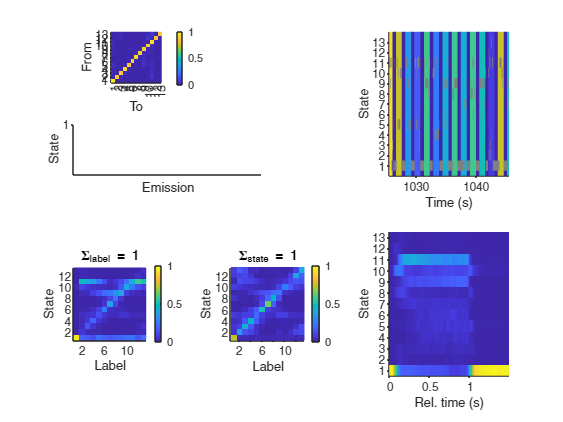

bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

## HMM fit to all labels, no hints 

n_emissions = 100; 
params = bs_default_params();
params.fit_hmm_prompt = 'no_hints';
params.hmm_algorithm = 'BaumWelch';
params.smooth = false;
params.binsize = 0.1;
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,trial_stim_type, recording_interval,params);
labels = unique(bin_labels);
n_states = length(labels);
[states,~,trans,emis] = bs_fit_hmm(bin_counts,n_states,n_emissions,bin_labels,params);

Fitting HMM
Done fitting


Confusion in state = 0.68. Lower is better.
Confusion in label = 0.61. Lower is better.
Entropy in labels = 3.2
Mutual information in states and labels = 0.81
Relative mutual information = 25%


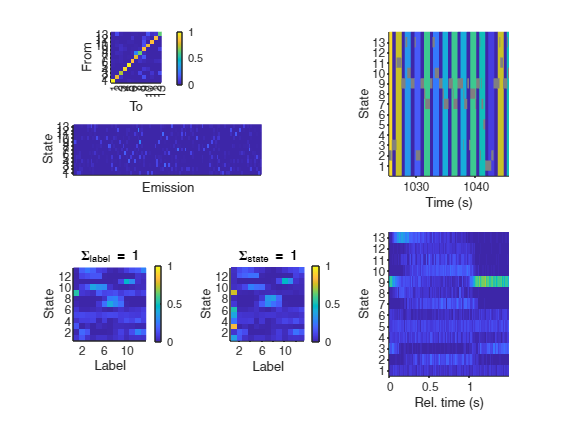

bs_results_hmm(trans,emis,bin_times,bin_labels,states,bin_times_rel);